Leo los datos del osciloscopio para una PRBS

data_prbs = open('prbs.CSV')

data_prbs = struct with fields:
        data: [30000×4 double]
    textdata: {10×6 cell}


data_prbs_t = data_prbs.data(:,2)

data_prbs_t =   -30.0000
  -29.9980
  -29.9960
  -29.9940
  -29.9920
  -29.9900
  -29.9880
  -29.9860
  -29.9840
  -29.9820


data_prbs_y = data_prbs.data(:,3)

data_prbs_y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


data_prbs_u = data_prbs.data(:,4)

data_prbs_u =     0.0396
    0.0396
    0.0792
    0.0396
    0.0396
    0.0792
    0.0792
    0.0792
    0.0396
    0.0792


ts = 0.002;

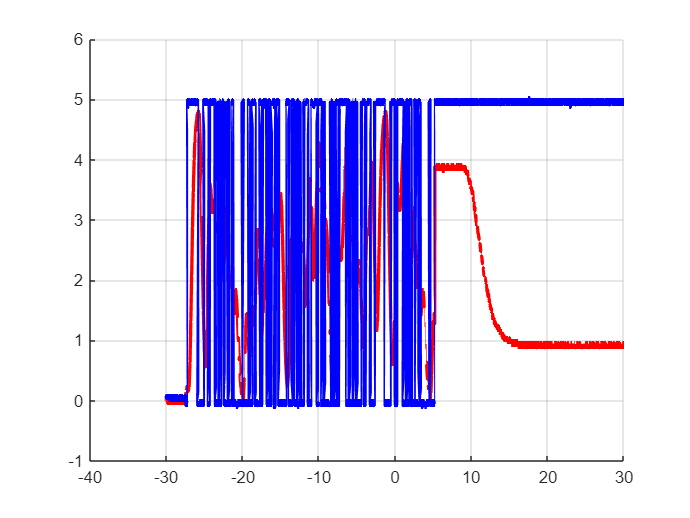

figure();
grid on; hold on;

plot(data_prbs_t, data_prbs_y, 'r', 'LineWidth', 2);
plot(data_prbs_t, data_prbs_u, 'b', 'LineWidth', 2);

starting_index = 5060

starting_index = 5060

ending_index = starting_index + length(0:ts:25.5)

ending_index = 17811

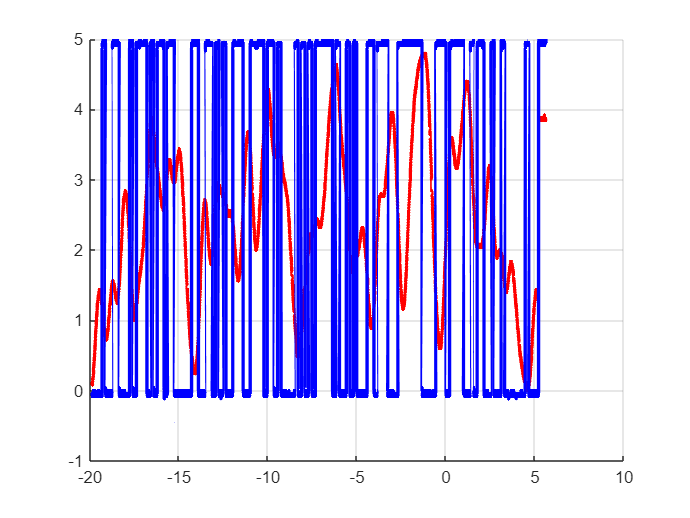


prbs_t = data_prbs_t(starting_index:ending_index);
prbs_y = data_prbs_y(starting_index:ending_index);
prbs_u = data_prbs_u(starting_index:ending_index);

figure();
grid on; hold on;

plot(prbs_t, prbs_y, 'r', 'LineWidth', 2);
plot(prbs_t, prbs_u, 'b', 'LineWidth', 2);